addpath('rx', 'tx','channel');
savepath;
Message = 'Hello bobr!';

%variant 4: len = 65, Nb = 8, Tcp = 1/4, dRS = 3, B = 11, f0 = 1.7

%Paremetrs
dRS = 3;
T = 0.25;
Nb = 8;
N0 = 0;
B = 11;
f0 = 1.7;

%Tx
encodedBits = symbolic_encoder(Message);
convEncodedBits = convolutional_encoder(encodedBits);
interleavedBits = interleaving(convEncodedBits);
disp(interleavedBits)

  Columns 1 through 43

   1   0   1   1   1   0   0   0   1   0   1   1   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   1   1   0   1   1   1   0   0   0   0   0   1   1   0   1   1

  Columns 44 through 86

   1   0   1   1   0   1   1   1   0   0   1   0   0   1   0   0   0   0   0   0   0   1   0   0   0   0   1   0   0   0   1   0   0   1   1   0   0   0   1   1   1   1   0

  Columns 87 through 129

   0   1   0   1   0   0   0   0   1   1   0   1   1   1   0   1   1   0   0   0   0   1   0   0   0   1   0   1   0   1   0   1   1   0   0   1   0   1   1   0   0   0   0

  Columns 130 through 172

   1   0   0   0   0   1   1   0   1   0   1   0   0   1   1   0   1   0   0   0   1   1   1   1   0   0   0   1   0   1   1   0   1   0   1   0   0   0   1   0   1   1   1

  Columns 173 through 176

   1   1   1   0



qpskSymbols = QPSK_mapper(interleavedBits);
disp(qpskSymbols);

  Columns 1 through 9

  -0.7070 + 0.7070i  -0.7070 - 0.7070i  -0.7070 + 0.7070i   0.7070 + 0.7070i  -0.7070 + 0.7070i  -0.7070 - 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 - 0.7070i

  Columns 10 through 18

  -0.7070 - 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 - 0.7070i  -0.7070 + 0.7070i  -0.7070 - 0.7070i  -0.7070 + 0.7070i   0.7070 + 0.7070i

  Columns 19 through 27

   0.7070 + 0.7070i  -0.7070 - 0.7070i   0.7070 - 0.7070i  -0.7070 - 0.7070i   0.7070 - 0.7070i  -0.7070 + 0.7070i  -0.7070 - 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i

  Columns 28 through 36

   0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 + 0.7070i  -0.7070 + 0.7070i   0.7070 + 0.7070i   0.7070 - 0.7070i   0.7070 + 0.7070i

  Columns 37 through 45

   0.7070 - 0.7070i   0.7070 + 0.7070i  -0.7070 - 0.7070i   0.7070 + 0.7070i   0.7070 - 0.7070i  -0.7070 - 0.7070i  -0.7070 + 0.7070i   0.7070 - 0.7070i   0.7070 - 0.7070i

  Columns 46

ofdmSymbols = ofdm_modulator(qpskSymbols, dRS, T);
disp(ofdmSymbols);

  Columns 1 through 9

   0.0668 + 0.0341i   0.0279 - 0.0484i  -0.0452 - 0.0273i  -0.0329 + 0.0339i   0.0545 + 0.0243i  -0.0134 - 0.0305i  -0.0085 + 0.0001i   0.0193 - 0.0172i  -0.0028 + 0.0191i

  Columns 10 through 18

  -0.0236 + 0.0504i  -0.0221 - 0.0498i   0.0589 - 0.0375i  -0.0031 + 0.0221i  -0.0137 + 0.0333i  -0.0421 + 0.0350i   0.0402 - 0.0590i   0.0123 - 0.0462i  -0.0412 + 0.0596i

  Columns 19 through 27

   0.0461 + 0.0009i  -0.0236 + 0.0452i  -0.0089 - 0.0767i   0.0181 - 0.0020i  -0.0068 + 0.0262i  -0.0334 + 0.0156i   0.0599 + 0.0063i  -0.0013 - 0.0320i  -0.0521 - 0.0050i

  Columns 28 through 36

   0.0133 + 0.0074i   0.0012 + 0.0382i   0.0532 - 0.0348i  -0.0546 + 0.0049i  -0.0013 - 0.0160i   0.0125 + 0.0206i   0.0182 + 0.0085i  -0.0170 - 0.0090i  -0.0207 - 0.0090i

  Columns 37 through 45

   0.0295 - 0.0143i   0.0049 + 0.0414i  -0.0301 - 0.0164i   0.0312 - 0.0277i  -0.0160 + 0.0316i   0.0041 + 0.0077i  -0.0256 - 0.0143i  -0.0279 - 0.0578i   0.2060 + 0.1091i

  Columns 46

%CHANNEL
AWGNbits = channel(ofdmSymbols, Nb, N0);
disp(AWGNbits);

   1.0e+05 *

  Columns 1 through 9

   0.3659 + 0.1867i   0.1530 - 0.2650i  -0.2474 - 0.1496i  -0.1799 + 0.1857i   0.2983 + 0.1329i  -0.0736 - 0.1671i  -0.0465 + 0.0007i   0.1055 - 0.0941i  -0.0152 + 0.1048i

  Columns 10 through 18

  -0.1294 + 0.2762i  -0.1213 - 0.2730i   0.3224 - 0.2052i  -0.0168 + 0.1210i  -0.0752 + 0.1821i  -0.2303 + 0.1916i   0.2204 - 0.3234i   0.0675 - 0.2531i  -0.2259 + 0.3263i

  Columns 19 through 27

   0.2526 + 0.0051i  -0.1294 + 0.2474i  -0.0490 - 0.4199i   0.0991 - 0.0112i  -0.0370 + 0.1436i  -0.1831 + 0.0855i   0.3279 + 0.0344i  -0.0071 - 0.1754i  -0.2851 - 0.0275i

  Columns 28 through 36

   0.0727 + 0.0404i   0.0066 + 0.2091i   0.2915 - 0.1908i  -0.2993 + 0.0269i  -0.0069 - 0.0876i   0.0683 + 0.1128i   0.0998 + 0.0465i  -0.0932 - 0.0495i  -0.1133 - 0.0493i

  Columns 37 through 45

   0.1615 - 0.0782i   0.0267 + 0.2265i  -0.1647 - 0.0896i   0.1708 - 0.1516i  -0.0874 + 0.1730i   0.0223 + 0.0423i  -0.1405 - 0.0785i  -0.1529 - 0.3165i   1.1284 + 0.5974i

%Rx
rx_ofdmSymbols = ofdm_demodulator(AWGNbits);
qpskDemodulatedBits = QPSK_demapper(rx_ofdmSymbols);
disp(qpskDemodulatedBits);

  Columns 1 through 29

     1     0     1     1     1     0     0     0     1     0     1     1     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     1     1

  Columns 30 through 58

     0     1     1     1     0     0     0     0     0     1     1     0     1     1     1     0     1     1     0     1     1     1     0     0     1     0     0     1     0

  Columns 59 through 87

     0     0     0     0     0     0     1     0     0     0     0     1     0     0     0     1     0     0     1     1     0     0     0     1     1     1     1     0     0

  Columns 88 through 116

     1     0     1     0     0     0     0     1     1     0     1     1     1     0     1     1     0     0     0     0     1     0     0     0     1     0     1     0     1

  Columns 117 through 145

     0     1     1     0     0     1     0     1     1     0     0     0     0     1     0     0     0     0     1     1     0     1     0     1     0     0     1     1 

deInterleavedBits = deinterleaving(qpskDemodulatedBits);
decodedBits = convolutional_decoder_viterbi(deInterleavedBits);
decodeMessage = symbolic_decoder(decodedBits);


%CHECK
if isequal(Message, decodeMessage)
    disp('Successfuly!');
    disp(['Original message: ', Message]);
    disp(['Decoded message: ', decodeMessage]);
else
    disp('Failed!');
    disp(['Original message: ', Message]);
    disp(['Decoded message: ', decodeMessage]);
end

Successfuly!


Original message: Hello bobr!


Decoded message: Hello bobr!


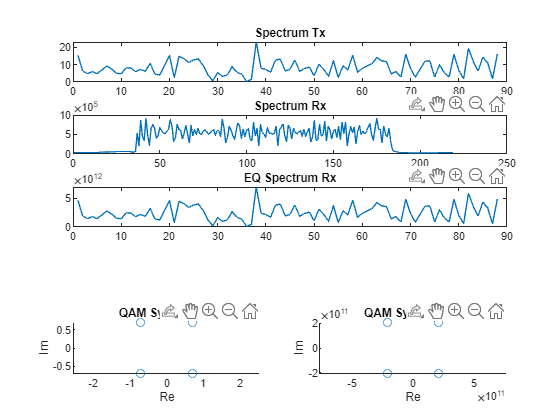

figure;

qpskTx = qpskSymbols;
qpskRx = rx_ofdmSymbols;
spectrumTx = abs(fft(qpskSymbols));
spectrumRx = abs(fft(AWGNbits));
spectrumEq = abs(fft(rx_ofdmSymbols));

% Верхние 3 графика (спектры)
subplot(5,1,1);
plot(spectrumTx);
title('Spectrum Tx');

subplot(5,1,2);
plot(spectrumRx);
title('Spectrum Rx');

subplot(5,1,3);
plot(spectrumEq);
title('EQ Spectrum Rx');

% Нижние 2 графика (QAM Symbols Rx)
subplot(5,2,9);
scatter(real(qpskTx), imag(qpskTx));
title('QAM Symbols Tx');
xlabel('Re'); ylabel('Im');
axis equal;

subplot(5,2,10);
scatter(real(qpskRx), imag(qpskRx));
title('QAM Symbols Rx');
xlabel('Re'); ylabel('Im');
axis equal;